# ECE 345/ME 380: Introduction to Control Systems

## Collaborative Quiz #4

### Location of poles and zeros of G(s)

num=[25]; den=[1 2 25];

### Step response of the open-loop system

sys=tf(num,den)

sys =
 
        25
  --------------
  s^2 + 2 s + 25
 
Continuous-time transfer function.



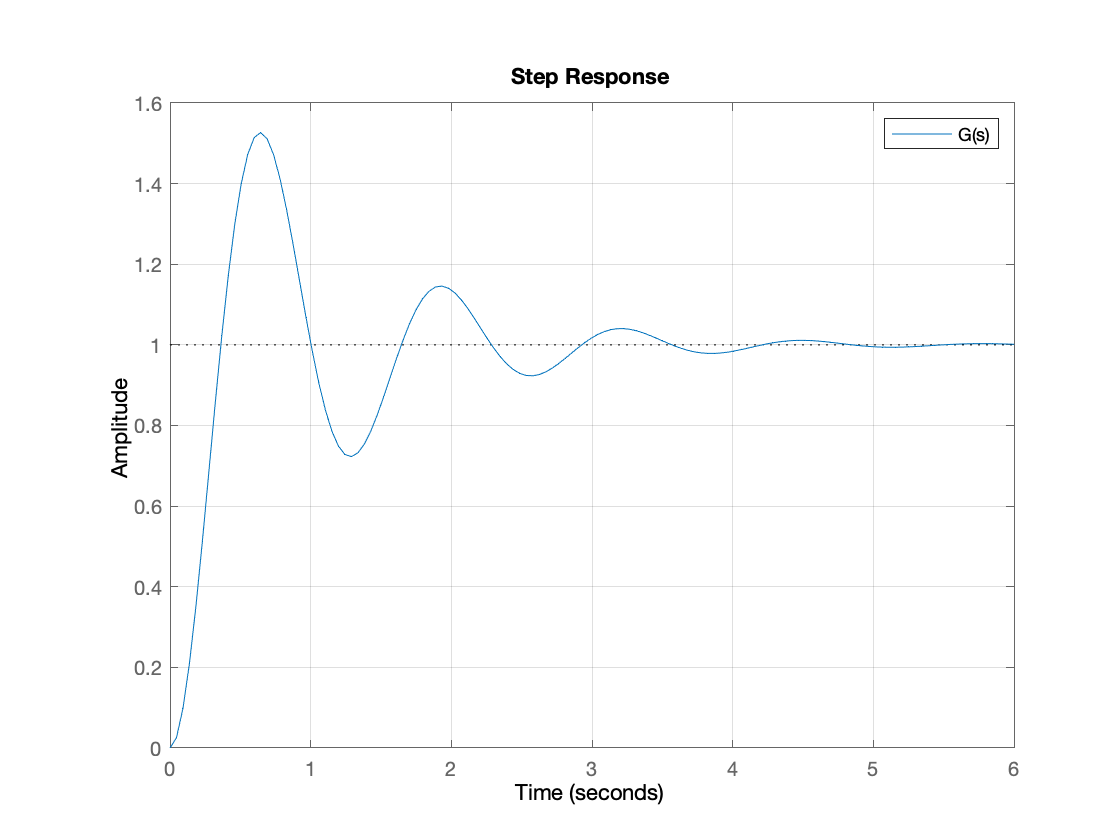

step(sys);grid;legend('G(s)','location','northeast')

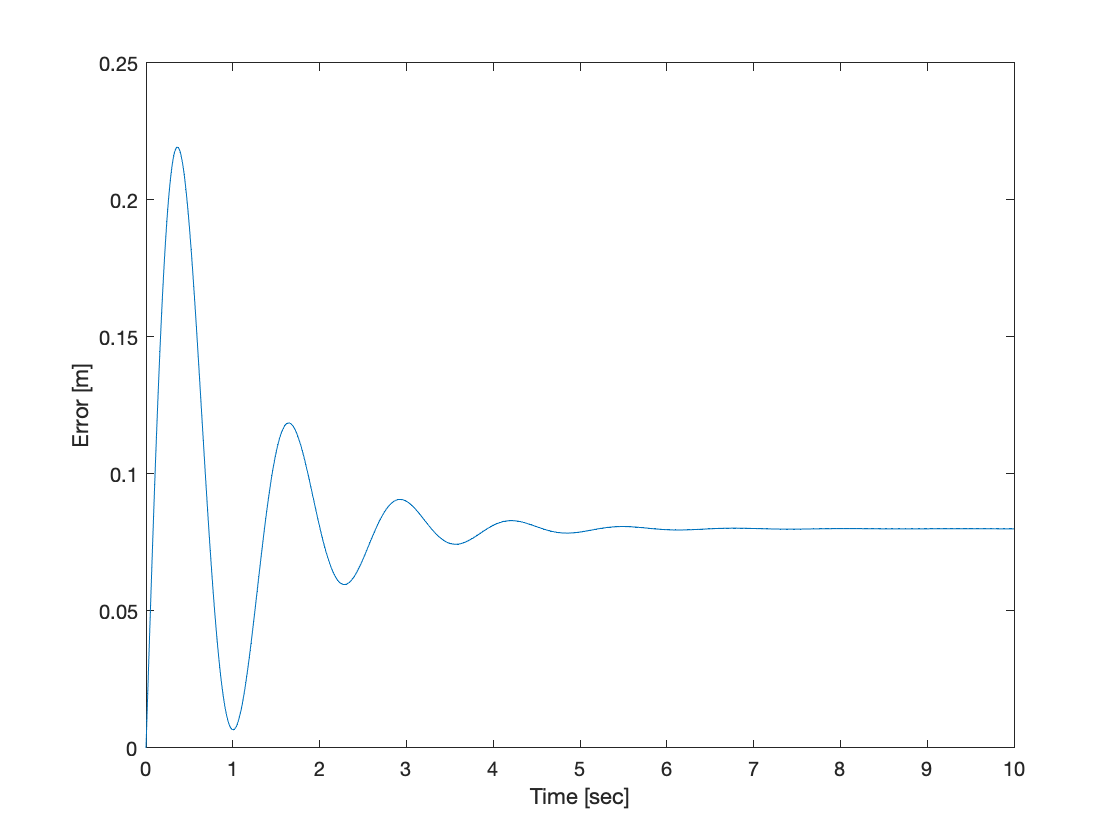

t = 0:.01:10;
r = t;
[y,tout] = lsim(sys,r,t);
plot(tout, r'-y);
xlabel('Time [sec]'); ylabel('Error [m]');